# Identificación automática de los puntos de linealizacion en programación de ganancias

`David Rodríguez Bascuñana`

## **Carga de datos iniciales y disposición de los rangos de ganancias**

load Datos_iniciales.mat

Num_L = 3;
Num_Mc = 4;

L_vec = [4 10.5 16];
Mc_vec = [0.1 4700 14100 23520];

IDATOS = cell(Num_L,Num_Mc);

Ts = 0.1;
Tend = 50;

vt = 0:Ts:Tend;

## Simulaciones sobre la grúa y obtención de datos

disp('Simulando ......, espere a que se presenten los resultados ')

Simulando ......, espere a que se presenten los resultados 



tic;
for i = 1:Num_L
    for j = 1:Num_Mc

L = L_vec(i);
Mc = Mc_vec(j);
 
Vector_Carro = [0 0;10 0;10 20000; 13 20000; 13 0; 20 0;20 -50000;25 -50000;25 0; Tend 0];
Vector_Portico = [0 0; Tend 0];

interruptor = -1;

[vt,estados,registrosC] = sim('Simulacion_RTG_ident.slx',vt); % Simulación de Movimiento de carro
    
entradasC = registrosC(:,1);
salidasC = registrosC(:,2);
IDATOS_C{i,j} = iddata(salidasC,entradasC,Ts);

Vector_Carro = [0 0; Tend 0];
Vector_Portico = [0 0;10 0;10 300000; 13 300000; 13 0;20 0; 20 -500000; 25 -500000; 25 0 ; Tend 0];
interruptor = 1;

[vt,estados,registrosP] = sim('Simulacion_RTG_ident.slx',vt); % Simulación de movimiento de Pórtico
    
entradasP = registrosP(:,1);
salidasP = registrosP(:,2);
IDATOS_P{i,j} = iddata(salidasP,entradasP,Ts);
    end
end
Tsim = toc;
InformeSim = ['Simulación terminada con una duración de ', num2str(Tsim),' segundos'];
disp(InformeSim)

Simulación terminada con una duración de 49.4508 segundos


## Análisis de datos y obtención de modelos lineales

FDTs_C = cell(Num_L,Num_Mc);
FDTs_P= cell(Num_L,Num_Mc);

for i = 1:Num_L % Cada L
    for j = 1:Num_Mc % Cada M_c
        
        opt = procestOptions('InitialCondition','zero');

        th_C = procest(IDATOS_C{i,j},'P3IU',opt); % se especifica el orden y forma del modelo
         if(th_C.Report.Fit.FitPercent<70)
             th_C = procest(IDATOS_C{i,j},'P2IU',opt);
         end

        th_P = procest(IDATOS_P{i,j},'P3IU',opt); % se especifica el orden y forma del modelo
         if(th_P.Report.Fit.FitPercent<70)
             th_P = procest(IDATOS_C{i,j},'P2IU',opt);
         end
        
        FDTs_C{i,j} = th_C;
        FDTs_P{i,j} = th_P;
    end
end

## Representación de la tabla de porcentaje de ajuste de los modelos y conversión de los modelos a espacio de estados

FITs_C = cell(Num_L,Num_Mc);
FITs_P = cell(Num_L,Num_Mc);

for i = 1:Num_L
    for j= 1:Num_Mc

        FITs_C{i,j} = FDTs_C{i,j}.Report.Fit.FitPercent;
        FITs_P{i,j} = FDTs_P{i,j}.Report.Fit.FitPercent;
    end
end
FITs_C

FITs_C = 3×4 cell array
    {[99.5148]}    {[99.6748]}    {[99.8470]}    {[99.9194]}
    {[99.7667]}    {[99.8734]}    {[99.9389]}    {[99.9556]}
    {[99.7039]}    {[99.8518]}    {[99.9436]}    {[99.9701]}


FITs_P

FITs_P = 3×4 cell array
    {[99.2760]}    {[99.4446]}    {[99.6271]}    {[99.7185]}
    {[99.3485]}    {[99.5020]}    {[99.6789]}    {[99.7640]}
    {[99.1894]}    {[99.2674]}    {[99.3918]}    {[99.4968]}


## Sintonización de los PIDs

PIDs_C = cell(Num_L,Num_Mc);
PIDs_P = cell(Num_L,Num_Mc);

BucleCerrado_C = cell(Num_L,Num_Mc);
BucleCerrado_P = cell(Num_L,Num_Mc);

CLPert_C = cell(Num_L,Num_Mc);
CLPert_P = cell(Num_L,Num_Mc);

for i = 1:Num_L
   for j = 1:Num_Mc

        % Se establecen los modelos
        G_C = tf(FDTs_C{i,j}); 
        G_P = tf(FDTs_P{i,j}); 

        % se configuran los PIDs a sintonizar
        PID_sintonizar_C = tunablePID('PID_C','pd'); 
        PID_sintonizar_P = tunablePID('PID_P','pd'); 

        % Se añaden analysis points para tener en cuenta la perturbacion
        X1_C = AnalysisPoint('X1_C'); 
        X1_P = AnalysisPoint('X1_P'); 

        % Se generan los bucles cerrados
        CL_C = feedback(G_C*X1_C*PID_sintonizar_C,1);  
        CL_P = feedback(G_P*X1_P*PID_sintonizar_P,1);  

        CL_C.InputName = 'ref';
        CL_C.OutputName = 'pos';

        CL_P.InputName = 'ref';
        CL_P.OutputName = 'pos';

        % Requisitos de tiempo de establecimiento y rechazo de perturbaciones
        Rref_C = TuningGoal.Tracking('ref','pos',10,0.01); % (Tiempo de respuesta, error en tanto por 1)
        Rpert_C = TuningGoal.Gain('X1_C','pos',0.1); % (Limite de la ganancia entre X1 y la salida)

        Rref_P = TuningGoal.Tracking('ref','pos',15,0.015); % (Tiempo de respuesta, error en tanto por 1)
        Rpert_P = TuningGoal.Gain('X1_P','pos',0.1); % (Limite de la ganancia entre X1 y la salida)

        % Se calculan los reguladores
        [CL_sint_C,fSoft,ghard,info_C] = systune(CL_C,[Rpert_C],[Rref_C]); % (especificaciones suaves, especificaciones fuertes)
        [CL_sint_P,fSoft,ghard,info_P] = systune(CL_P,[Rpert_P],[Rref_P]); % (especificaciones suaves, especificaciones fuertes)
        BucleCerrado_C{i,j} = CL_sint_C;
        BucleCerrado_P{i,j} = CL_sint_P;

        % Se almacenan los PIDs
        PIDs_C{i,j} = info_C.Blocks.PID_C; 
        PIDs_P{i,j} = info_P.Blocks.PID_P; 

        %CLPert_C{i,j} = getIOTransfer(CL_C,'X1_C','pos');
        %CLPert_P{i,j} = getIOTransfer(CL_P,'X1_P','pos');


   end
end

Final: Soft = 0.00285, Hard = 1.1843, Iterations = 41


Final: Soft = 0.000446, Hard = 1.1887, Iterations = 42


Final: Soft = 0.00278, Hard = 1.1941, Iterations = 54


Final: Soft = 0.000463, Hard = 1.2312, Iterations = 42


Final: Soft = 0.0027, Hard = 1.2029, Iterations = 58


Final: Soft = 0.000476, Hard = 1.2631, Iterations = 41


Final: Soft = 0.0029, Hard = 1.1579, Iterations = 49


Final: Soft = 0.000473, Hard = 1.2544, Iterations = 41


Final: Soft = 0.0034, Hard = 1.3972, Iterations = 49


Final: Soft = 0.000972, Hard = 2.1396, Iterations = 41


Final: Soft = 0.00333, Hard = 1.3508, Iterations = 43


Final: Soft = 0.0011, Hard = 2.2262, Iterations = 40


Final: Soft = 0.00303, Hard = 1.2817, Iterations = 59


Final: Soft = 0.000875, Hard = 2.0555, Iterations = 40


Final: Soft = 0.00287, Hard = 1.2576, Iterations = 52


Final: Soft = 0.000486, Hard = 1.3374, Iterations = 63


Final: Soft = 0.00369, Hard = 1.5216, Iterations = 55


Final: Soft = 0.0029, Hard = 3.2553, Iterations = 38


Final: Soft = 0.00357, Hard = 1.4584, Iterations = 48


Final: Soft = 0.00278, Hard = 3.1977, Iterations = 38


Final: Soft = 0.00331, Hard = 1.3458, Iterations = 50


Final: Soft = 0.00182, Hard = 2.7033, Iterations = 40


Final: Soft = 0.00306, Hard = 1.2949, Iterations = 51


Final: Soft = 0.0012, Hard = 2.3179, Iterations = 39


## Representación de resultados

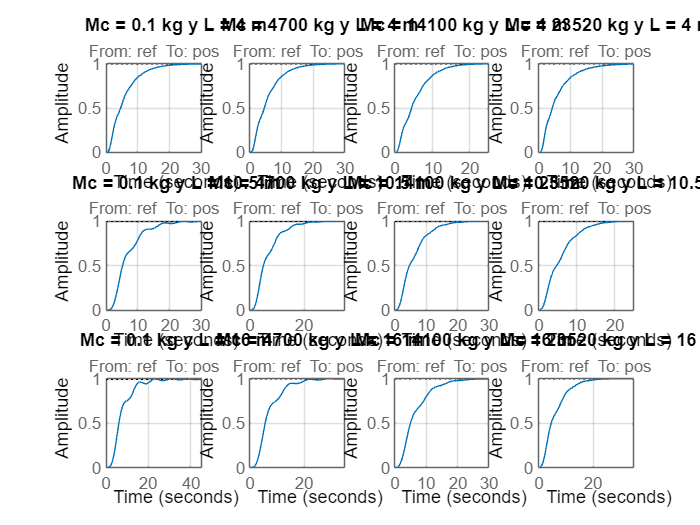

% Representación Bucle Carro
k = 1;
for i = 1:Num_L
    for j= 1:Num_Mc

        subplot(Num_L,Num_Mc,k)
        step(BucleCerrado_C{i,j}), grid on
        title("Mc = "+num2str(Mc_vec(j))+" kg y L = "+num2str(L_vec(i))+" m");
        k = k+1;
    end
end

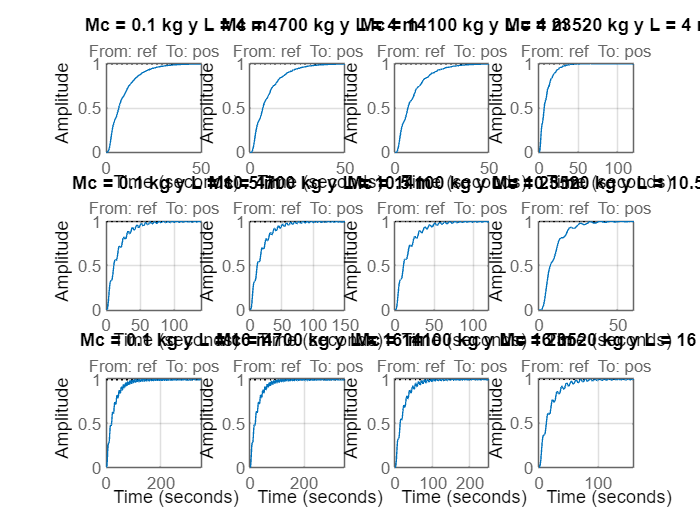

% Representación Bucle Pórtico
k = 1;
for i = 1:Num_L
    for j= 1:Num_Mc

        subplot(Num_L,Num_Mc,k)
        step(BucleCerrado_P{i,j}), grid on
        title("Mc = "+num2str(Mc_vec(j))+" kg y L = "+num2str(L_vec(i))+" m");
        k = k+1;
    end
end
hold off

## Creación de las superficies de planificación de ganancias

Como los reguladores son PD solo tenemos 2 ganancias, Kp y Kd

% se generan las matrices con las ganancias
Kp_C_mat = zeros(Num_L,Num_Mc);
Kp_P_mat = zeros(Num_L,Num_Mc);
Kd_C_mat = zeros(Num_L,Num_Mc);
Kd_P_mat = zeros(Num_L,Num_Mc);

k = 1;
for i = 1:Num_L
    for j= 1:Num_Mc
        
        Kp_C_mat(i,j) = PIDs_C{i,j}.Kp.Value;
        Kp_P_mat(i,j) = PIDs_P{i,j}.Kp.Value;
        Kd_C_mat(i,j) = PIDs_C{i,j}.Kd.Value;
        Kd_P_mat(i,j) = PIDs_P{i,j}.Kd.Value;
        
    end
end

save MATRICES_DE_GANANCIAS Kp_C_mat Kp_P_mat Kd_C_mat Kd_P_mat